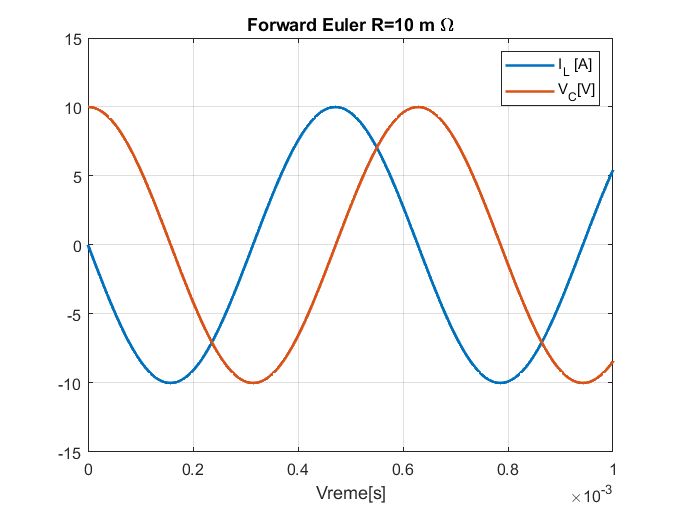

close all
clear
h=1e-6;% Ts korak simulacije
time=0:h:1e-3;
L=100e-6;
C=100e-6;
wn=1/sqrt(L*C);
fn=wn/2/pi;
Tn=1/fn;
xv=zeros(2,length(time));
lteefe=zeros(2,length(time));
lteebe=zeros(2,length(time));
lteebl=zeros(2,length(time));
xv(:,1)=[0;10];
%Forward Euler
R=10e-3;
T=	[1-(R*h)/L,	-h/L;h/C,	1];
%Forward Euler
for i=2:length(time)
    xv(:,i)=T*xv(:,i-1);
    lteefe(1,i)=-1/2*h*(xv(1,i)-xv(1,i-1));
    lteefe(2,i)=-1/2*h*(xv(2,i)-xv(2,i-1));
end
figure()
plot(time,xv(1,:),'LineWidth',1.6);
hold on
plot(time,xv(2 ,:),'LineWidth',1.6);
grid on
legend('I_L [A]','V_C[V]')
xlabel('Vreme[s]')
title('Forward Euler R=10 m \Omega')

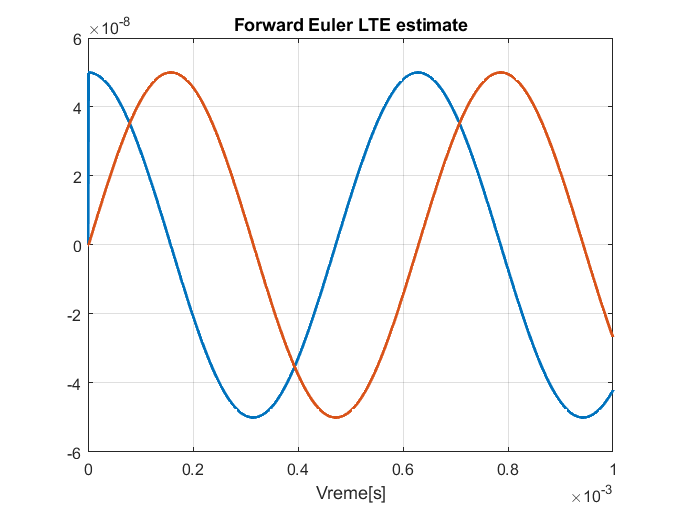


figure()
plot(time,lteefe(1 ,:),'LineWidth',1.6)
hold on
plot(time,lteefe(2 ,:),'LineWidth',1.6)
grid on 
hold off
xlabel('Vreme[s]')
title('Forward Euler LTE estimate')

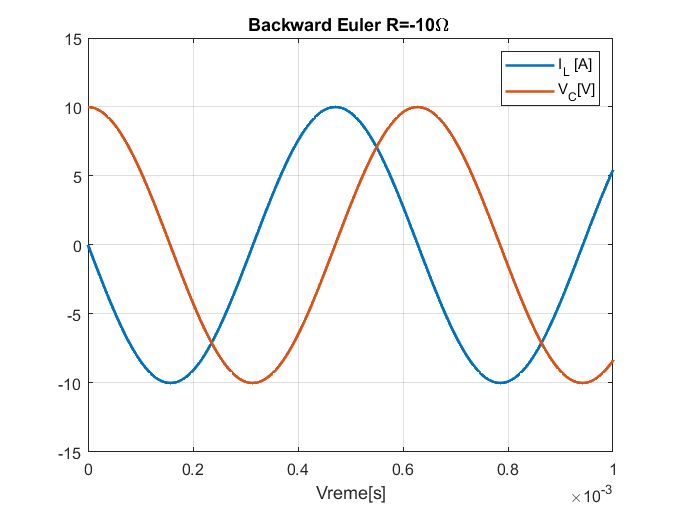

%Backward Euler
Rbe=-10e-3;
Tbe=[(C*L)/(h^2+C*Rbe*h+C*L),	-(C*h)/(h^2+C*Rbe*h+C*L);...
    (L*h)/(h^2+C*Rbe*h+C*L),(C*Rbe*h+C*L)/(h^2+C*Rbe*h+C*L)];
	
for i=2:length(time)
    xv(:,i)=Tbe*xv(:,i-1);
    lteebe(1,i)=1/2*h*(xv(1,i)-xv(1,i-1));
    lteebe(2,i)=1/2*h*(xv(2,i)-xv(2,i-1));
end
figure()
plot(time,xv(1,:),'LineWidth',1.6);
hold on
plot(time,xv(2 ,:),'LineWidth',1.6);
grid on
legend('I_L [A]','V_C[V]')
xlabel('Vreme[s]')
title('Backward Euler R=-10\Omega ')

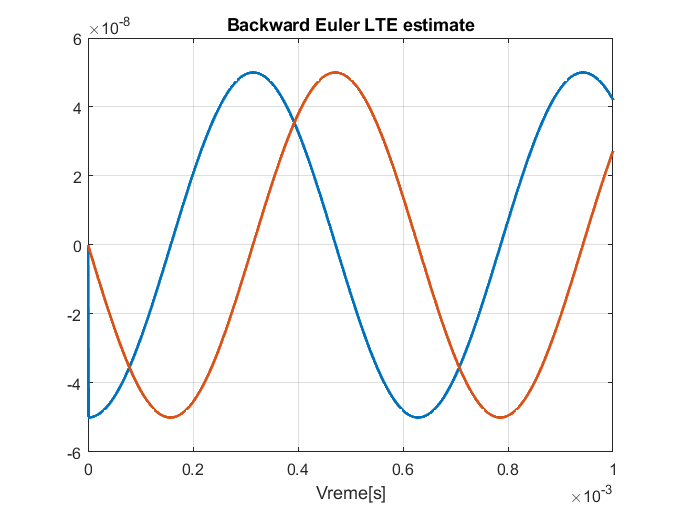

figure()
plot(time,lteebe(1 ,:),'LineWidth',1.6)
hold on
plot(time,lteebe(2 ,:),'LineWidth',1.6)
grid on 
hold off
xlabel('Vreme[s]')
title('Backward Euler LTE estimate')

% Bilinear transform
wd=2/h*atan(wn*h/2);
(wn-wd)/wn

ans = 8.3332e-06

wd=(1-1e-6)*wn;

mora da se smanji h

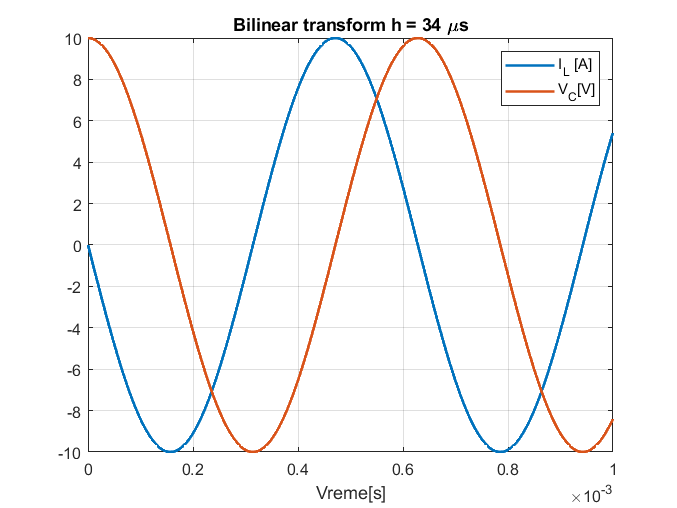

syms h
hsol=vpasolve(2/h*atan(wn*h/2)==wd,h);
hbl=eval(hsol);
Tbl=[-(hbl^2-4*C*L)/(hbl^2+4*C*L),	-(4*C*hbl)/(hbl^2+4*C*L);(4*L*hbl)/(hbl^2+4*C*L),	-(hbl^2-4*C*L)/(hbl^2+4*C*L)];
time=0:hbl:1e-3;	
for i=2:length(time)
    xv(:,i)=Tbl*xv(:,i-1);
    if i>2
        lteebl(1,i)=hbl*(xv(1,i)-2*xv(1,i-1)+xv(1,i-2))/12;
        lteebl(2,i)=hbl*(xv(2,i)-2*xv(2,i-1)+xv(2,i-2))/12;
    end
end

figure()
plot(time,xv(1,:),'LineWidth',1.6);
hold on
plot(time,xv(2 ,:),'LineWidth',1.6);
grid on
legend('I_L [A]','V_C[V]')
xlabel('Vreme[s]')
title('Bilinear transform h = 34 \mus')

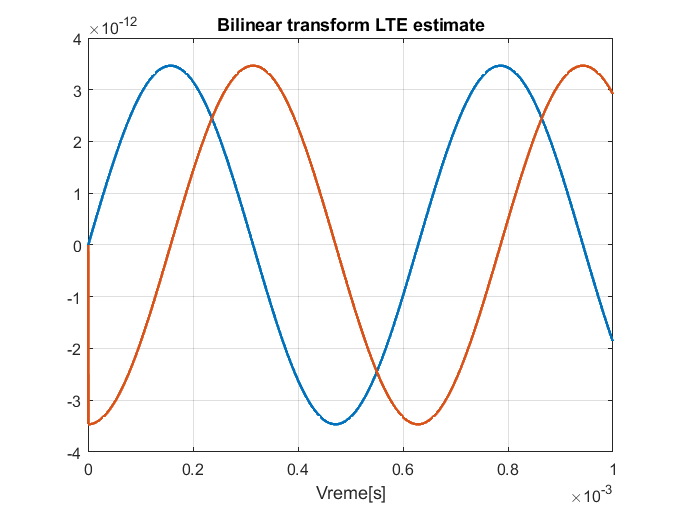


figure()
plot(time,lteebl(1 ,:),'LineWidth',1.6);
hold on
plot(time,lteebl(2 ,:),'LineWidth',1.6);
grid on 
hold off
xlabel('Vreme[s]')
title('Bilinear transform LTE estimate')